Q6 a)

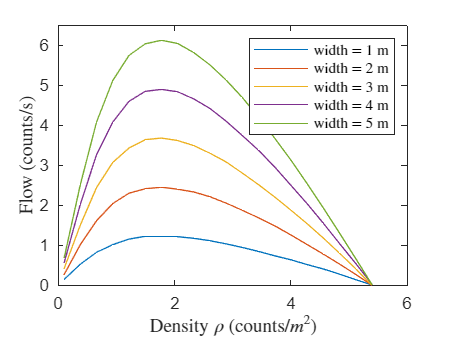

rng('default')

% create array of 'test values'

n = 100;
sig = 0.75;

% test densities
% density < 10
rho = linspace(0.1,5.4,20);
% test widths
% width > 0.8
w = 1:5;

% initialise results
flow = zeros(20,5);
for i = 1:length(w)
    for j = 1:length(rho)
        RV = sig*(sqrt(-2*log(rand(1)))*cos(-2*pi*rand(1)));
        flow(j,i) = 100*w(i)*rho(j)*(1.34*(1-exp(-1.914*((1/rho(j))-(1/5.4)))))+RV;
        flow(j,i) = round(flow(j,i))/100;
    end
end

figure;
plot(rho, flow)
legend(["width = 1 m","width = 2 m","width = 3 m","width = 4 m","width = 5 m"], 'Interpreter','latex')
xlabel("Density \(\rho\) (counts/\(m^2\))", 'Interpreter','latex')
ylabel("Flow (counts/s)", 'Interpreter','latex')
xlim([0,6])
ylim([0,6.5])